# **Project:** How does the performance of a Greenpower car change during a race?

I am going to use fake data to analyse how the performance of a Greenpower car change during a race.

**Main objectives:**

- See what conclusions can be made about the efficiency of empress.

- Identify the source of what causes empress to slow down during race.

- Use the data to make the process of looking for solutions that allow empress to maintain speed for as long as possible during races easier.

Display Table:

GreenpowerRaceData_fake_ = readtable('Greenpower race data (fake).xlsx');

GreenpowerRaceData_fake_

GreenpowerRaceData_fake_ = 15×7 table
    LapNumber    LapTime_secs_    Var3    BatteryVoltage_V_    BatteryCurrent_A_    TrackDistance_metres_    TotalRaceTime_mins_
    _________    _____________    ____    _________________    _________________    _____________________    ___________________

        1            220.4        NaN             24                   28                   3200                     120        
        2            239.4        NaN            NaN                  NaN                    NaN                     NaN        
        3            260.8        NaN            NaN                  NaN                    NaN                     NaN        
        4            279.7        NaN            NaN                  NaN     

Import data from table into variables:

lapNumber = GreenpowerRaceData_fake_ .LapNumber

lapNumber =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10
    11
    12
    13
    14
    15


lapTime = GreenpowerRaceData_fake_ .LapTime_secs_

lapTime =   220.4000
  239.4000
  260.8000
  279.7000
  300.5000
  319.3000
  340.2000
  360.9000
  379.6000
  399.2000
  420.3000
  440.6000
  459.5000
  480.1000
  499.5000


batteryVoltage = GreenpowerRaceData_fake_ .BatteryVoltage_V_

batteryVoltage =     24
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN


batteryCurrent = GreenpowerRaceData_fake_ .BatteryCurrent_A_

batteryCurrent =     28
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN


lapDistance = GreenpowerRaceData_fake_ .TrackDistance_metres_

lapDistance =         3200
         NaN
         NaN
         NaN
         NaN
         NaN
         NaN
         NaN
         NaN
         NaN
         NaN
         NaN
         NaN
         NaN
         NaN


totalRaceTime = GreenpowerRaceData_fake_ .TotalRaceTime_mins_

totalRaceTime =    120
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN


Calculate Average lap time:

avgLapTime = mean(lapTime)

avgLapTime = 360

Fastest lap:

fastestLap = min(lapTime)

fastestLap = 220.4000

Slowest lap:

slowestLap = max(lapTime)

slowestLap = 499.5000

Difference between fastest and slowest lap:

diff = slowestLap - fastestLap

diff = 279.1000

Calculate the speed of each lap:

lapDistanceDivider = [3200;3200;3200;3200;3200;3200;3200;3200;3200;3200;3200;3200;3200;3200;3200]

lapDistanceDivider =         3200
        3200
        3200
        3200
        3200
        3200
        3200
        3200
        3200
        3200
        3200
        3200
        3200
        3200
        3200


eachLapSpeed = lapDistanceDivider./lapTime 

eachLapSpeed =    14.5191
   13.3668
   12.2699
   11.4408
   10.6489
   10.0219
    9.4062
    8.8667
    8.4299
    8.0160
    7.6136
    7.2628
    6.9641
    6.6653
    6.4064


Calculate Average lap speed:

avgLapSpeed = lapDistance(1)/avgLapTime

avgLapSpeed = 8.8889

Graph to display the time taken for empress to complete each lap:

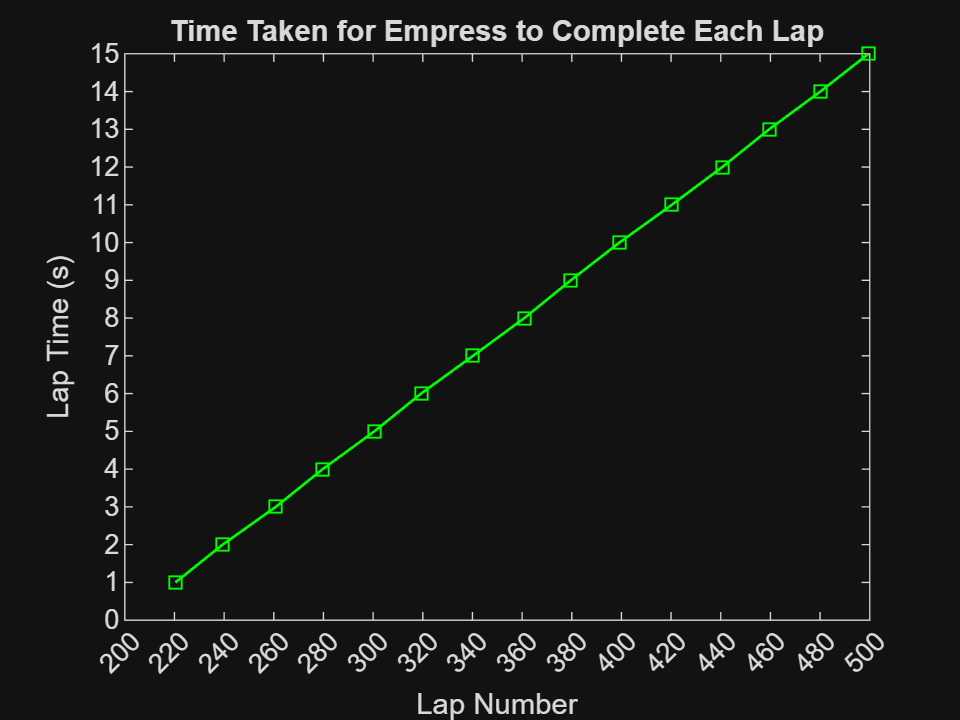

 plot(lapTime,lapNumber,"gs-", LineWIdth = 1)
 xlabel("Lap Number")
 ylabel("Lap Time (s)")
 title("Time Taken for Empress to Complete Each Lap")
 set(gca, "ytick", 0:1:15)
 set(gca, "xtick", 0:20:500)

Graph to display the speed empress had each lap:

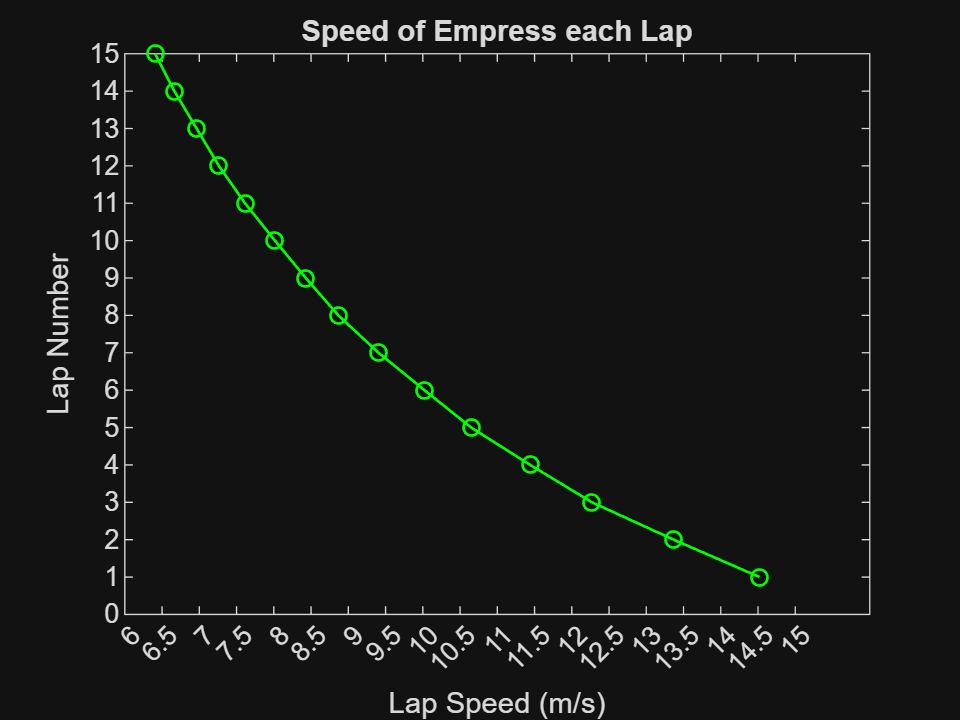

 plot(eachLapSpeed,lapNumber,"go-", LineWIdth = 1)
 xlabel("Lap Speed (m/s)")
 ylabel("Lap Number")
 title("Speed of Empress each Lap")
 set(gca, "xtick", 0:0.5:15)
 set(gca, "ytick", 0:1:15)

### **Analysis of graphs:**

**Did performance improve or decline?**

Empress' performance declined steadily 

**Were the lap times consistent?**

The strong positive correlation between lap time and lap number show the lap times were not consistent. Empress got slower and slower as the race went on.

**At what point did performance change?**

The speed of empress decreased quite steadily from the first lap. However, this is probably because the data is fake. In real races I have been to where empress fails to maintain initial speed, usually the time taken for the car to complete each lap is around the same for the first 30 minutes then gradually gets slower and slower until it's walking pace.

**What might have caused the change?**

- The battery started at low current 

- A driver could have braked often which drains the battery

**Possible solutions?**

- Use a battery with higher current e.g. 32A

- Encourage drivers not to brake as much as possible

- ?

### **Final conclusions from this project:**

**Benefits:**

While it took longer to make calculations and draw graphs from data using MATLAB rather than excel it allowed me to develop the coding skills I learnt from the MATLAB course I did in a practical and fun way. There are lots of parallels between coding in MATLAB and python, so it also helped me practice concepts in both coding languages. This is why I think it would be helpful for other students at Greenpower to explore.

Furthermore, MATLAB is a platform that is used to allow engineers and data analysts to make calculations and visualise data, which are two career paths I am highly interested in and now know I would have fun having either one of these careers because of the MATLAB course and this project. 

In terms of answering my initial question (How does the performance of a Greenpower car change during a race?), MATLAB certainly helped me to do this. The graphs show a clear answer. More team collaboration will be essential to use this data to look for solutions that allow empress to maintain speed for as long as possible.

**Next steps to improve this project:**

- Would like to a third graph showing power consumption over a race but would appreciate guidance about how to do this because I’m not sure if it’s possible to record the current, voltage, resistance etc. of the batteries over a race.

- Look for more efficient ways to code. This should be achieved through reading through more of the MATLAB help centre documentation and practice.

- Collaborate with the team to get suggestions about how to improve empress’ performance.

Export code and results as a pdf

 export("greenpower_race_analyser.mlx")

ans = '/MATLAB Drive/greenpower_race_analyser.pdf'